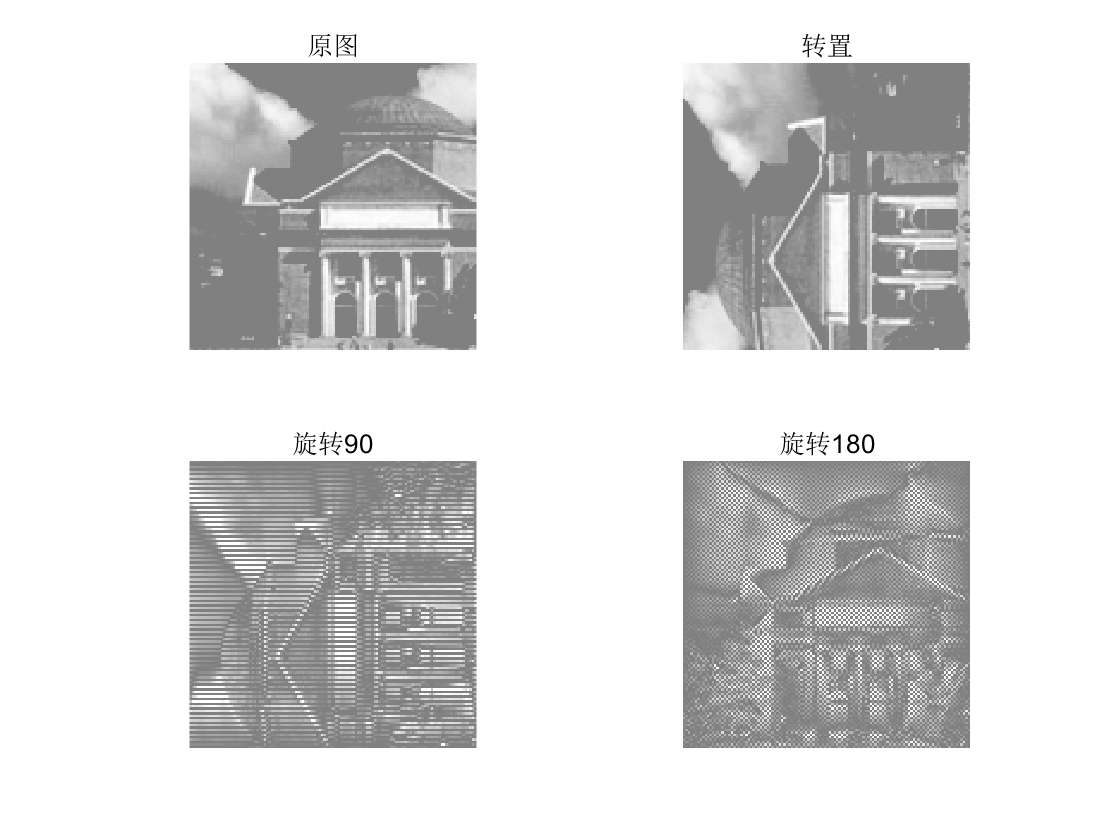

clear
load hall
P = double(hall_gray(1:120,1:120))-128;
[N,~] = size(P);

C = dct2(P);
C1 = ctranspose(C); % 转置
C2 = rot90(C); % 旋转90
C3 = rot90(C2); % 旋转180

Q = uint8(idct2(C))+128;
Q1 = uint8(idct2(C1))+128;
Q2 = uint8(idct2(C2))+128;
Q3 = uint8(idct2(C3))+128;

subplot(2,2,1);
imshow(Q);
title('原图');
subplot(2,2,2);
imshow(Q1);
title('转置');
subplot(2,2,3);
imshow(Q2);
title('旋转90');
subplot(2,2,4);
imshow(Q3);
title('旋转180');